% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 15;
avgNum = 10;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/Mouse Plasma Data/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Reading in Data

file_name = "Outlier_Removed_Standard_Time.csv";
file_path = data_path+file_name;
fulldata = readmatrix(file_path);

n = 6; % donor number
% 16 donors donor ID's

don = [1,2,3,4,5,6];
 
% trimming blood plasma data and standard samples data to these WN's
t1 = 500;
t2 = 1800;


data = fulldata;  
data(:, data(1, :) <= t1) = [];
data(:, data(1, :) >= t2) = [];
data = [[fulldata(:, 1:3)] data];

shifts = data(1, 4:end);

% Sample Set 1 for Donors 3.3, 9.2, 8.4

% correction and NIST correction
file_name = "NIST1.csv";
file_path = strcat(data_path,file_name);
nist1 = readmatrix(file_path);

file_name = "Polystyrene1.csv";
file_path = strcat(data_path,file_name);
poly1 = readmatrix(file_path);
poly = mean(poly1(2:end,:));

file_name = "Silicon1.csv";
file_path = strcat(data_path,file_name);
Si1 = readmatrix(file_path);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

[preprocessed1, train_set1, test_set1] = prepSet(data, [1], -1, -1, [6,1,10,11,8,2,5,6,7]);

% Sample Set 2 for Donors 4.5, 3.4, 9.5

% correction and NIST correction
file_name = "NIST2.csv";
file_path = strcat(data_path,file_name);
nist1 = readmatrix(file_path);

file_name = "Polystyrene2.csv";
file_path = strcat(data_path,file_name);
poly1 = readmatrix(file_path);
poly = mean(poly1(2:end,:));

file_name = "Silicon2.csv";
file_path = strcat(data_path,file_name);
Si1 = readmatrix(file_path);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

[preprocessed2, train_set2, test_set2] = prepSet(data, [2], -1, -1, [6,1,10,11,8,2,5,6,7]);

% Sample Set 3 for Donors 8.3, 4.3

% correction and NIST correction
file_name = "NIST3.csv";
file_path = strcat(data_path,file_name);
nist1 = readmatrix(file_path);

file_name = "Polystyrene3.csv";
file_path = strcat(data_path,file_name);
poly1 = readmatrix(file_path);
poly = mean(poly1(2:end,:));

file_name = "Silicon3.csv";
file_path = strcat(data_path,file_name);
Si1 = readmatrix(file_path);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

[preprocessed3, train_set3, test_set3] = prepSet(data, [3], -1, -1, [6,1,10,11,8,2,5,6,7]);

% Sample Set 4 for Donors 4.4, 8.5, 9.4

% correction and NIST correction
file_name = "NIST4.csv";
file_path = strcat(data_path,file_name);
nist1 = readmatrix(file_path);

file_name = "Polystyrene4.csv";
file_path = strcat(data_path,file_name);
poly1 = readmatrix(file_path);
poly = mean(poly1(2:end,:));

file_name = "Silicon4.csv";
file_path = strcat(data_path,file_name);
Si1 = readmatrix(file_path);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

[preprocessed4, train_set4, test_set4] = prepSet(data, [4], -1, -1, [6,1,10,11,8,2,5,6,7]);

% Sample Set 5 for Donors 3.2, 4.2, 8.2

% correction and NIST correction
file_name = "NIST5.csv";
file_path = strcat(data_path,file_name);
nist1 = readmatrix(file_path);

file_name = "Polystyrene5.csv";
file_path = strcat(data_path,file_name);
poly1 = readmatrix(file_path);
poly = mean(poly1(2:end,:));

file_name = "Silicon5.csv";
file_path = strcat(data_path,file_name);
Si1 = readmatrix(file_path);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

[preprocessed5, train_set5, test_set5] = prepSet(data, [5], -1, -1, [6,1,10,11,8,2,5,6,7]);

% Sample Set 6 for Donors 9.3, 3.5

% correction and NIST correction
file_name = "NIST6.csv";
file_path = strcat(data_path,file_name);
nist1 = readmatrix(file_path);

file_name = "Polystyrene6.csv";
file_path = strcat(data_path,file_name);
poly1 = readmatrix(file_path);
poly = mean(poly1(2:end,:));

file_name = "Silicon6.csv";
file_path = strcat(data_path,file_name);
Si1 = readmatrix(file_path);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

[preprocessed6, train_set6, test_set6] = prepSet(data, [6], -1, -1, [6,1,10,11,8,2,5,6,7]);

%preprocessed = [preprocessed1; preprocessed2; preprocessed3; preprocessed4; preprocessed5; preprocessed6];
%train_set = [train_set1; train_set2; train_set3; train_set4; train_set5; train_set6];
%test_set = [test_set1; test_set2; test_set3; test_set4; test_set5; test_set6];
preprocessed = [preprocessed4; preprocessed5; preprocessed6];
train_set = [train_set4; train_set5; train_set6];
test_set = [test_set4; test_set5; test_set6];

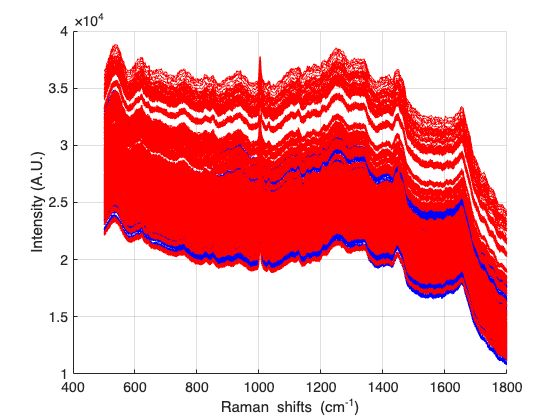

% PLOTS OF THE RAW AND PREPROCESSED DATA

fig1 = figure;
ax1 = axes(fig1);
grid on;
hold on;
plot(ax1, shifts, data(data(:, 2) == 0 & data(:,1) == 1, 4:end), 'b')
plot(ax1, shifts, data(data(:, 2) == 0 & data(:,1) == 2, 4:end), 'b')
plot(ax1, shifts, data(data(:, 2) == 0 & data(:,1) == 3, 4:end), 'b')
plot(ax1, shifts, data(data(:, 2) == 0 & data(:,1) == 4, 4:end), 'b')
plot(ax1, shifts, data(data(:, 2) == 0 & data(:,1) == 5, 4:end), 'b')
plot(ax1, shifts, data(data(:, 2) == 0 & data(:,1) == 6, 4:end), 'b')
plot(ax1, shifts, data(data(:, 2) == 4 & data(:,1) == 1, 4:end), 'r')
plot(ax1, shifts, data(data(:, 2) == 4 & data(:,1) == 2, 4:end), 'r')
plot(ax1, shifts, data(data(:, 2) == 4 & data(:,1) == 3, 4:end), 'r')
plot(ax1, shifts, data(data(:, 2) == 4 & data(:,1) == 4, 4:end), 'r')
plot(ax1, shifts, data(data(:, 2) == 4 & data(:,1) == 5, 4:end), 'r')
plot(ax1, shifts, data(data(:, 2) == 4 & data(:,1) == 6, 4:end), 'r')
%plot(ax1, shifts, data(data(:, 2) == 4, 4:end), 'r')
xlabel(ax1, 'Raman shifts (cm^{-1})')
ylabel(ax1, 'Intensity (A.U.)')
ax1.FontSize = 14;
hold off;

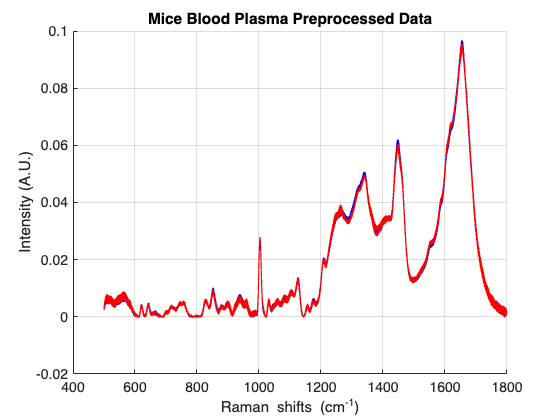

fig2 = figure;
ax2 = axes(fig2);
grid on;
hold on;
plot(ax2, corr_shifts, preprocessed(preprocessed(:, 2) == 1, 4:end), 'b')
plot(ax2, corr_shifts, preprocessed(preprocessed(:, 2) == 5, 4:end), 'r')
xlabel(ax2, 'Raman shifts (cm^{-1})')
ylabel(ax2, 'Intensity (A.U.)')
title('Mice Blood Plasma Preprocessed Data')
ax2.FontSize = 14;
hold off;

format long;
[snr_control, closestShift_control] = SNR_loc(preprocessed(preprocessed(:, 2) == 1, 4:end), corr_shifts, 1003)

snr_control =   54.836456054166263


closestShift_control =      1.002775794326467e+03


[snr_irradiated, closestShift_irradiated] = SNR_loc(preprocessed(preprocessed(:, 2) == 5, 4:end), corr_shifts, 1003)

snr_irradiated =   79.406745059429824


closestShift_irradiated =      1.002775794326467e+03


% Creating Arrays of Control and Irradiated preprocessed data

Control = [];
Irradiated = [];
size_processed = size(preprocessed);
for i = 1:size_processed(1,1)
    if preprocessed(i,2) == 1
        Control = [Control;preprocessed(i,:)];
    else if preprocessed(i,2) == 5
            Irradiated = [Irradiated;preprocessed(i,:)];
    end
    end
end

% Finding mean spectra

mean_control = mean(Control);
mean_irradiated = mean(Irradiated);

Dif_Spectra = mean_control-mean_irradiated;

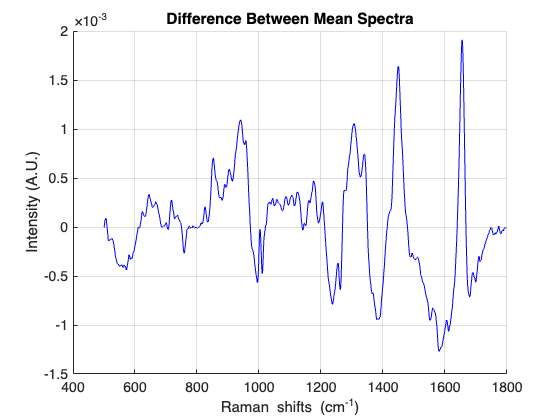

fig3 = figure;
ax3 = axes(fig3);
grid on;
hold on;
plot(ax3, corr_shifts, Dif_Spectra(4:end), 'b')
xlabel(ax3, 'Raman shifts (cm^{-1})')
ylabel(ax3, 'Intensity (A.U.)')
title('Difference Between Mean Spectra')
ax3.FontSize = 14;
hold off;

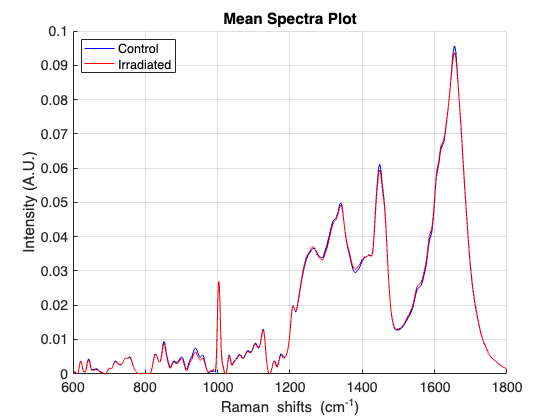

fig4 = figure;
ax4 = axes(fig4);
grid on;
hold on;
plot(ax4, corr_shifts(101:end), mean_control(104:end), 'b')
plot(ax4, corr_shifts(101:end), mean_irradiated(104:end), 'r')
xlabel(ax4, 'Raman shifts (cm^{-1})')
ylabel(ax4, 'Intensity (A.U.)')
title('Mean Spectra Plot')
ax4.FontSize = 14;
legend('Control', 'Irradiated', 'location', 'northwest');
hold off;

%writematrix(Dif_Spectra, "Difference_Spectra.csv")

%writematrix(corr_shifts, "Wavenumbers.csv")

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = abs((av1 - av2)) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [snr, closestShift] = SNR_loc(spectra, shifts, wavenumber)

    [~, closestIndex] = min(abs(shifts - wavenumber));

    closestShift = shifts(closestIndex);

    peaks = spectra(:, closestIndex + 3);

    snr = mean(peaks)/std(peaks);

end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end